ptCloudWithMark =   pointCloud のプロパティ:

     Location: [60754×3 double]
        Count: 60754
      XLimits: [-56.3963 64.3720]
      YLimits: [-21.4013 119.3711]
      ZLimits: [-128.3727 367.0965]
        Color: []
       Normal: []
    Intensity: []


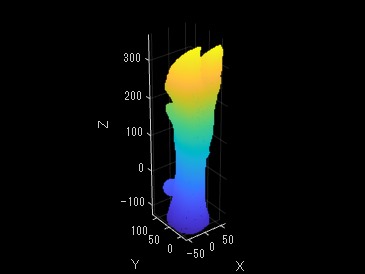

ptCloudWithMarker = stlread("WithMark.stl");
ptCloudWithMark = pointCloud(ptCloudWithMarker.Points*1000)

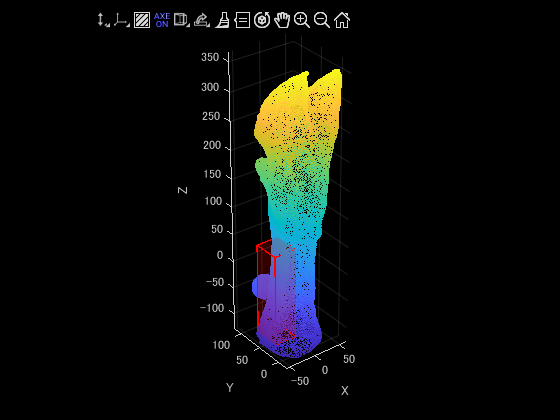

pcshowWithAxes(ptCloudWithMark)
ax = gca;
roi = images.roi.Cuboid(ax, 'Rotatable', 'all', 'Color', 'r');
draw(roi);

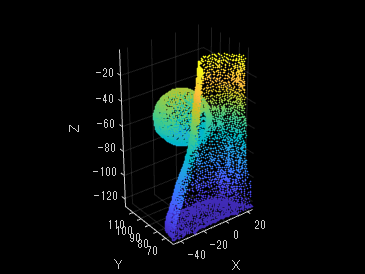

xmin = roi.Position(1);
ymin = roi.Position(2);
zmin = roi.Position(3);
xmax = roi.Position(4)+roi.Position(1);
ymax = roi.Position(5)+roi.Position(2);
zmax = roi.Position(6)+roi.Position(3);

newroi = [xmin xmax ymin ymax zmin zmax];
indices = findPointsInROI(ptCloudWithMark, newroi);
newPoint = select(ptCloudWithMark, indices);
pcshowWithAxes(newPoint);

maxDist = 2;2

ans = 2

[model, inlierIn, out] = pcfitsphere(ptCloudWithMark, maxDist, 'MaxNumTrials',20000, 'SampleIndices',indices);
selSphere = select(ptCloudWithMark, inlierIn)

selSphere =   pointCloud のプロパティ:

     Location: [4411×3 double]
        Count: 4411
      XLimits: [-29.5411 10.0740]
      YLimits: [77.5688 119.3711]
      ZLimits: [-76.4957 -35.9890]
        Color: []
       Normal: []
    Intensity: []


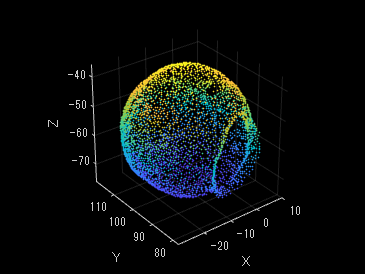

oSphere = select(ptCloudWithMark, out);
pcshowWithAxes(selSphere);

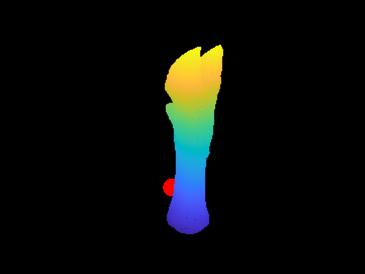

pcshow(ptCloudWithMark, "AxesVisibility","on");
hold on;             
pcshow(selSphere.Location, 'r');
hold off;

% yli = selSphere.YLimits;
spt = selSphere.Location

spt =   -14.7971   80.1108  -58.9834
  -14.8679   79.5418  -59.3205
  -14.6117   79.7605  -58.9616
  -14.5075   80.3738  -53.9545
  -14.4302   80.2983  -55.4271
  -14.4472   79.7319  -54.6555
  -16.1172   78.1882  -58.1012
  -15.9696   78.3497  -57.7042
  -15.6441   78.9332  -57.7327
  -14.4514   79.6908  -55.3690


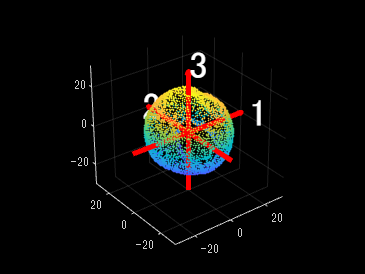

beforecut = scoreandAxes(spt);

cutspt = spt(spt(:,2) > 87,:);

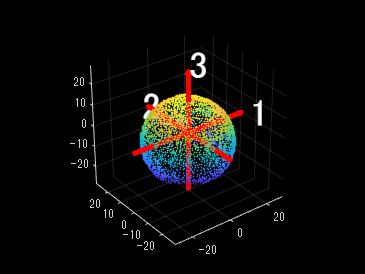

% pcshow(cutspt);
score = scoreandAxes(cutspt);

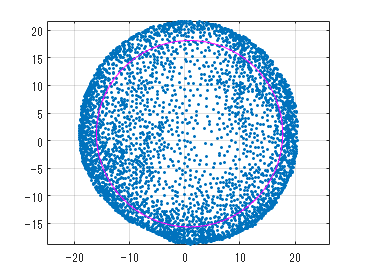

proJ = score(:,[1 2]);
figure();
x = proJ(:,1);
y = proJ(:,2);
plot(x, y, '.');

hold on;
grid on;
% 円近似
[cxe, cye, re] = CircleFitting(x, y);
theta=[0:0.1:2*pi 0];
xe=re*cos(theta)+cxe;
ye=re*sin(theta)+cye;
plot(xe,ye,'-m');hold on;
daspect([1 1 1]);
grid on;
axis equal;
hold off;

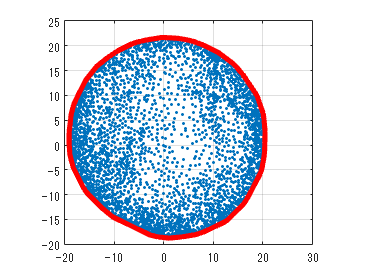

K = convhull(x, y);
kx = x(K); ky = y(K);
plot(x, y, '.');hold on;
grid on;
plot(kx,ky,'r', 'LineWidth',3.5);
daspect([1 1 1]);
hold off;

[cxk, cyk, rk] = CircleFitting(kx, ky);
cxk

cxk = 0.8045

cyk

cyk = 1.5268

rk

rk = 19.9943

rk * 2

ans = 39.9886

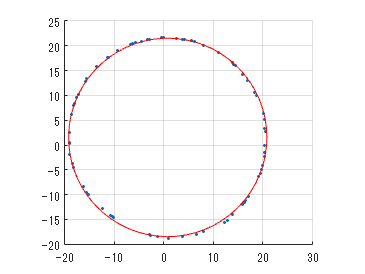

% theta=[0:0.1:2*pi 0];
x_k=rk*cos(theta)+cxk;
y_k=rk*sin(theta)+cyk;
figure();
hold on; grid on;
plot(kx, ky, '.');
daspect([1 1 1]);
plot(x_k, y_k, 'r');
hold off;

kpro = [kx ky];

[thetaSorted, rhoSorted] = sortPointOnPolar(kpro);
figure()
polarplot(thetaSorted, rhoSorted, '.');

tfrom = [-cxk, -cyk, 0];
pt = pointCloud(score);
tfPoint = transform(pt, 0, 'x', tfrom);
tfp = tfPoint.LocatonpcshowWithAxes(tfPoint);


tfproJ = tfp(:, [1 2]);
tf_x = tfproJ(:,1);
tf_y = tfproJ(:,2);
figure;

plot(tf_x, tf_y, '.');
grid on;
daspect([1 1 1])

tfK = convhull(tf_x, tf_y);
tfkx = tf_x(tfK); tfky = tf_y(tfK);

tfproK = [tfkx tfky];
[tfx, tfy, tfr] = CircleFitting(tfkx, tfky);

% 凸包で選んだ点群のソート
[tftheta, tfrho] = sortPointOnPolar(tfproK);
polarplot(tftheta, tfrho, '.');
max(tfrho)
min(tfrho)

ｘ軸，y軸方向の両端座標より半径算出

抽出個数が少ない

tx = tfPoint.XLimits;
ty = tfPoint.YLimits;
txlen = abs(tx(1))+abs(tx(2))
tylen = abs(ty(1))+abs(ty(2))

凸包で選ばれた点群の半径を二倍にして平均をとる

tfrho;
dia = tfrho*2;
rhomean = mean(tfrho)
esrho = rhomean*2
mean(dia)